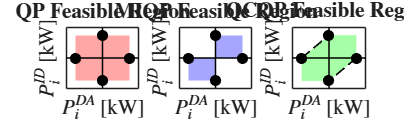

% =========================================================
% Feasible Region Illustration
% =========================================================

clear; clc; close all;

% ---------------------------------------------------------
% Parameters (P_DA_max slightly larger than P_ID_max)
% ---------------------------------------------------------
P_DA_max = 1.2;
P_ID_max = 1.0;

% ---------------------------------------------------------
% Create figure
% ---------------------------------------------------------
figure('Color','w');

%% ========================================================
%  Common settings
% ==========================================================
xlim_vals = 1.35 * [-P_DA_max, P_DA_max];
ylim_vals = 1.35 * [-P_ID_max, P_ID_max];

pointSize = 70;
alphaVal  = 0.35;

%% ========================================================
%  Subplot 1 : Full rectangle
% ==========================================================
subplot(1,3,1);
hold on; box on;

% Red rectangle
patch( ...
    [-P_DA_max, -P_DA_max,  P_DA_max,  P_DA_max], ...
    [-P_ID_max,  P_ID_max,  P_ID_max, -P_ID_max], ...
    'r', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

% Axes
plot(xlim_vals,[0 0],'k','LineWidth',1.2);
plot([0 0],ylim_vals,'k','LineWidth',1.2);

% Mark the four parametric points
scatter([0,0,P_DA_max,-P_DA_max], ...
        [P_ID_max,-P_ID_max,0,0], ...
        pointSize,'k','filled');

% % Point labels
% text(0, P_ID_max, ...
%     '$\left(0,\;P^{ID,\max}_i\right)$', ...
%     'Interpreter','latex', ...
%     'VerticalAlignment','bottom', ...
%     'HorizontalAlignment','left', ...
%     'FontSize',11);
% 
% text(0, -P_ID_max, ...
%     '$\left(0,\;-P^{ID,\max}_i\right)$', ...
%     'Interpreter','latex', ...
%     'VerticalAlignment','top', ...
%     'HorizontalAlignment','left', ...
%     'FontSize',11);
% 
% text(P_DA_max, 0, ...
%     '$\left(P^{DA,\max}_i,\;0\right)$', ...
%     'Interpreter','latex', ...
%     'VerticalAlignment','bottom', ...
%     'HorizontalAlignment','left', ...
%     'FontSize',11);
% 
% text(-P_DA_max, 0, ...
%     '$\left(-P^{DA,\max}_i,\;0\right)$', ...
%     'Interpreter','latex', ...
%     'VerticalAlignment','bottom', ...
%     'HorizontalAlignment','right', ...
%     'FontSize',11);

% Labels
xlabel('$P^{DA}_i$ [kW]','Interpreter','latex', 'FontSize',16);
ylabel('$P^{ID}_i$ [kW]','Interpreter','latex', 'FontSize',16);

% Formatting
axis equal;
xlim(xlim_vals);
ylim(ylim_vals);

% Remove numbers from axes
set(gca,'XTick',[],'YTick',[]);

title('\textbf{QP Feasible Region}','Interpreter','latex', 'FontSize', 16, 'FontWeight','bold');

%% ========================================================
%  Subplot 2 : First and third quadrants only
% ==========================================================
subplot(1,3,2);
hold on; box on;

% First quadrant rectangle
patch( ...
    [0, 0, P_DA_max, P_DA_max], ...
    [0, P_ID_max, P_ID_max, 0], ...
    'b', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

% Third quadrant rectangle
patch( ...
    [0, 0, -P_DA_max, -P_DA_max], ...
    [0, -P_ID_max, -P_ID_max, 0], ...
    'b', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

% Axes
plot(xlim_vals,[0 0],'k','LineWidth',1.2);
plot([0 0],ylim_vals,'k','LineWidth',1.2);

% Mark points
scatter([0,0,P_DA_max,-P_DA_max], ...
        [P_ID_max,-P_ID_max,0,0], ...
        pointSize,'k','filled');

% Labels
xlabel('$P^{DA}_i$ [kW]','Interpreter','latex', 'FontSize',16);
ylabel('$P^{ID}_i$ [kW]','Interpreter','latex', 'FontSize',16);

% Formatting
axis equal;
xlim(xlim_vals);
ylim(ylim_vals);

set(gca,'XTick',[],'YTick',[]);

title('\textbf{MIQP Feasible Region}','Interpreter','latex', 'FontSize',16, 'FontWeight','bold');

%% ========================================================
%  Subplot 3 : Hexagonal polygon
% ==========================================================
subplot(1,3,3);
hold on; box on;

% Hexagon vertices
x_hex = [-P_DA_max, ...
          0, ...
          P_DA_max, ...
          P_DA_max, ...
          0, ...
         -P_DA_max];

y_hex = [0, ...
         P_ID_max, ...
         P_ID_max, ...
         0, ...
        -P_ID_max, ...
        -P_ID_max];

% Green polygon
patch(x_hex, y_hex, ...
      'g', ...
      'FaceAlpha', alphaVal, ...
      'EdgeColor', 'none');

% Diagonal boundary lines
plot([ P_DA_max, 0], [0, -P_ID_max], ...
    'k--','LineWidth',1.2);

plot([-P_DA_max, 0], [0,  P_ID_max], ...
    'k--','LineWidth',1.2);

% Axes
plot(xlim_vals,[0 0],'k','LineWidth',1.2);
plot([0 0],ylim_vals,'k','LineWidth',1.2);

% Mark points
scatter([0,0,P_DA_max,-P_DA_max], ...
        [P_ID_max,-P_ID_max,0,0], ...
        pointSize,'k','filled');

% Labels
xlabel('$P^{DA}_i$ [kW]','Interpreter','latex', 'FontSize',16);
ylabel('$P^{ID}_i$ [kW]','Interpreter','latex', 'FontSize',16);

% Formatting
axis equal;
xlim(xlim_vals);
ylim(ylim_vals);

set(gca,'XTick',[],'YTick',[]);

title('\textbf{QCQP Feasible Region}','Interpreter','latex', 'FontSize',16, 'FontWeight','bold');

% ---------------------------------------------------------
% Overall formatting
% ---------------------------------------------------------
set(gcf,'Position',[100 100 1400 420]);

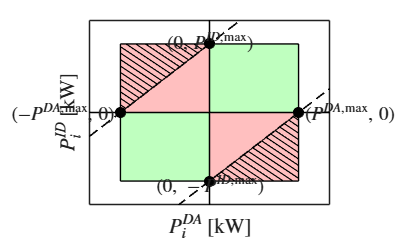




P_DA_max = 1.3;
P_ID_max = 1.0;
figure('Color','w');

xlim_vals = 1.35 * [-P_DA_max, P_DA_max];
ylim_vals = 1.35 * [-P_ID_max, P_ID_max];

pointSize = 70;
alphaVal  = 0.25;

hold on; box on;

% First quadrant rectangle
patch( ...
    [0, 0, P_DA_max, P_DA_max], ...
    [0, P_ID_max, P_ID_max, 0], ...
    'g', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'k');

% Third quadrant rectangle
patch( ...
    [0, 0, -P_DA_max, -P_DA_max], ...
    [0, -P_ID_max, -P_ID_max, 0], ...
    'g', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'k');

%2nd and 4th quadrant triangle
patch( ...
    [0, 0, P_DA_max, P_DA_max], ...
    [0, -P_ID_max, -P_ID_max, 0], ...
    'r', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

patch( ...
    [0, 0, -P_DA_max, -P_DA_max], ...
    [0, P_ID_max, P_ID_max, 0], ...
    'r', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

%2nd and 4th quadrant not allowed triangle
h1 = patch([P_DA_max, P_DA_max, 0],...
    [0, -P_ID_max, -P_ID_max],...
    'w',...
          'FaceColor','none',...
          'EdgeColor','k');

hatchfill2(h1,'HatchStyle','single',...
             'HatchAngle',-45,...
             'HatchDensity',30,...
             'HatchColor','k');

h2 = patch([0, -P_DA_max, -P_DA_max],...
    [P_ID_max, P_ID_max, 0],...
    'w',...
          'FaceColor','none',...
          'EdgeColor','k');

hatchfill2(h2,'HatchStyle','single',...
             'HatchAngle',-45,...
             'HatchDensity',30,...
             'HatchColor','k');

% Diagonal boundary lines

% Current axis limits
xmin = xlim_vals(1);
xmax = xlim_vals(2);

% Slope of diagonal
m = P_ID_max/P_DA_max;

x = [xmin xmax];

% Upper-left diagonal
y1 = m*(x + P_DA_max);

% Lower-right diagonal
y2 = m*(x - P_DA_max);

plot(x,y1,'k--','LineWidth',1.2);
plot(x,y2,'k--','LineWidth',1.2);


% Axes
plot(xlim_vals,[0 0],'k','LineWidth',1.2);
plot([0 0],ylim_vals,'k','LineWidth',1.2);

% Mark points
scatter([0,0,P_DA_max,-P_DA_max], ...
        [P_ID_max,-P_ID_max,0,0], ...
        pointSize,'k','filled');

offset_x = 0.05*P_DA_max;
offset_y = 0.05*P_ID_max;

text(0, P_ID_max+offset_y,...
    '$(0,\;P^{ID,\max})$',...
    'Interpreter','latex',...
    'HorizontalAlignment','center',...
    'FontSize',14);

text(0, -P_ID_max-offset_y,...
    '$(0,\;-P^{ID,\max})$',...
    'Interpreter','latex',...
    'HorizontalAlignment','center',...
    'FontSize',14);

text(P_DA_max+offset_x, 0,...
    '$(P^{DA,\max},\;0)$',...
    'Interpreter','latex',...
    'HorizontalAlignment','left',...
    'FontSize',14);

text(-P_DA_max-offset_x, 0,...
    '$(-P^{DA,\max},\;0)$',...
    'Interpreter','latex',...
    'HorizontalAlignment','right',...
    'FontSize',14);

% Labels
xlabel('$P^{DA}_i$ [kW]','Interpreter','latex', 'FontSize',16);
ylabel('$P^{ID}_i$ [kW]','Interpreter','latex', 'FontSize',16);

% Formatting
axis equal;
xlim(xlim_vals);
ylim(ylim_vals);

set(gca,'XTick',[],'YTick',[]);

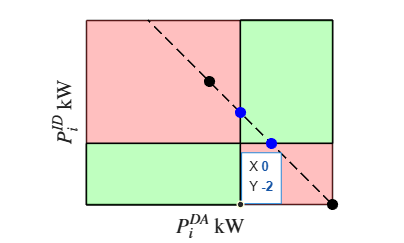

P_DA_max = 1.3;
P_ID_max = 1.0;
figure('Color','w');

x_lower = -5;
x_upper = 3;
y_lower = -2;
y_upper = 4;

xlim_vals = [x_lower, x_upper];
ylim_vals = [y_lower, y_upper];

pointSize = 70;
alphaVal  = 0.25;

hold on; box on;

% First quadrant rectangle
patch( ...
    [0, 0, x_upper, x_upper], ...
    [0, y_upper, y_upper, 0], ...
    'g', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'k');

% Third quadrant rectangle
patch( ...
    [0, 0, x_lower, x_lower], ...
    [0, y_lower, y_lower, 0], ...
    'g', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'k');

%2nd and 4th quadrant triangle
patch( ...
    [0, 0, x_upper, x_upper], ...
    [0, y_lower, y_lower, 0], ...
    'r', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

patch( ...
    [0, 0, x_lower, x_lower], ...
    [0, y_upper, y_upper, 0], ...
    'r', ...
    'FaceAlpha', alphaVal, ...
    'EdgeColor', 'none');

% Diagonal boundary lines

% Current axis limits
xmin = xlim_vals(1);
xmax = xlim_vals(2);

% Slope of diagonal
m = P_ID_max/P_DA_max;

x = [x_lower x_upper];
Pg = 1;

y1 = Pg-x;



plot(x,y1,'k--','LineWidth',1.2);



% Axes
plot(xlim_vals,[0 0],'k','LineWidth',1.2);
plot([0 0],ylim_vals,'k','LineWidth',1.2);

% Mark points
scatter([-1,3], ...
        [2,-2], ...
        pointSize,'k','filled');

scatter([0,1], ...
         [1,0], ...
         pointSize,'b','filled');

offset_x = 0.05*P_DA_max;
offset_y = 0.05*P_ID_max;


% Labels
xlabel('$P^{DA}_i$ kW','Interpreter','latex', 'FontSize',16);
ylabel('$P^{ID}_i$ kW','Interpreter','latex', 'FontSize',16);

% Formatting
axis equal;
xlim(xlim_vals);
ylim(ylim_vals);

set(gca,'XTick',[],'YTick',[]);

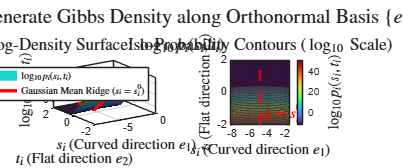

% =========================================================================
% Script: plot_degenerate_gaussian_pdf_logscale.m
% Description: Visualizes p_i(s_i, t_i) on a logarithmic color scale so
%              subtle density variations across all orders of magnitude 
%              are clearly visible.
% =========================================================================

clear; clc; close all;

%% 1. Model Parameters
dt       = 1.0;            % Time step duration [h]
alpha_ID = 0.5;            % Intraday penalty coefficient
eta      = 0.9;            % Trade-off parameter (0 < eta <= 1)
pi_DA    = 45;             % Day-ahead price [EUR/MWh]
pi_ID    = 40;             % Intraday price [EUR/MWh]

%% 2. Orthonormal Basis Projections & Distribution Parameters
norm_v_sq = (1 / eta) + 1;
norm_v    = sqrt(norm_v_sq);

c_s = (dt / norm_v) * ((pi_DA / sqrt(eta)) - pi_ID);
c_t = (dt / norm_v) * (pi_DA + (pi_ID / sqrt(eta)));

sigma_s_sq = 1 / (alpha_ID * dt * norm_v_sq);
sigma_s    = sqrt(sigma_s_sq);
s_0        = - c_s / (alpha_ID * dt * norm_v_sq);

%% 3. Coordinate Grid
s_range = linspace(s_0 - 3.5 * sigma_s, s_0 + 3.5 * sigma_s, 200);
t_range = linspace(-2, 2, 200);   % Tighter range prevents numerical underflow/overflow
[S, T]  = meshgrid(s_range, t_range);

%% 4. Factorized Density
P_s = (1 / (sqrt(2 * pi * sigma_s_sq))) .* exp(- (S - s_0).^2 / (2 * sigma_s_sq));
P_t = exp(- c_t .* T);

% Full density (floor at 1e-12 to avoid log(0) in visualization)
P = max(P_s .* P_t, 1e-12);
logP = log10(P);

%% 5. Plotting
figure('Color', 'w', 'Position', [100, 100, 1200, 500]);

% --- Subplot 1: 3D Surface with Log-Scaled Color ---
subplot(1, 2, 1);
surf(S, T, logP, 'EdgeColor', 'none', 'FaceAlpha', 0.95);
hold on;
colormap(turbo);
shading interp;
lighting gouraud;
camlight headlight;

% Highlight the mean ridge along e_2 where s = s_0
t_ridge = linspace(min(t_range), max(t_range), 200);
logP_ridge = log10(max((1 / (sqrt(2 * pi * sigma_s_sq))) .* exp(- c_t .* t_ridge), 1e-12));
plot3(s_0 * ones(size(t_ridge)), t_ridge, logP_ridge, 'r-', 'LineWidth', 2.5);

grid on; box on;
view(-35, 30);
xlabel('$s_i$ (Curved direction $e_1$)', 'Interpreter', 'latex', 'FontSize', 11);
ylabel('$t_i$ (Flat direction $e_2$)', 'Interpreter', 'latex', 'FontSize', 11);
zlabel('$\log_{10} p_i(s_i, t_i)$', 'Interpreter', 'latex', 'FontSize', 11);
title('Log-Density Surface: $\log_{10} p_i(s_i, t_i)$', 'Interpreter', 'latex', 'FontSize', 13);
legend({'$\log_{10} p_i(s_i, t_i)$', 'Gaussian Mean Ridge ($s_i = s_i^0$)'}, ...
    'Interpreter', 'latex', 'Location', 'northeast');

% --- Subplot 2: 2D Iso-Contour Map (Log Contours) ---
subplot(1, 2, 2);
levels = linspace(min(logP(:)), max(logP(:)), 25);
contourf(S, T, logP, levels, 'LineColor', [0.25 0.25 0.25], 'LineWidth', 0.4);
hold on;

% Center axis
xline(s_0, '--r', 'LineWidth', 2, 'Label', '$s_i = s_i^0$', ...
    'Interpreter', 'latex', 'LabelOrientation', 'horizontal', ...
    'FontSize', 11, 'LabelVerticalAlignment', 'bottom');

% Colorbar setup
cb = colorbar;
cb.Label.Interpreter = 'latex';
cb.Label.String = '$\log_{10} p_i(s_i, t_i)$';
cb.Label.FontSize = 11;

grid on; box on;
xlabel('$s_i$ (Curved direction $e_1$)', 'Interpreter', 'latex', 'FontSize', 11);
ylabel('$t_i$ (Flat direction $e_2$)', 'Interpreter', 'latex', 'FontSize', 11);
title('Iso-Probability Contours ($\log_{10}$ Scale)', 'Interpreter', 'latex', 'FontSize', 13);

sgtitle('Degenerate Gibbs Density along Orthonormal Basis $\{e_1, e_2\}$', ...
    'Interpreter', 'latex', 'FontSize', 15, 'FontWeight', 'bold');

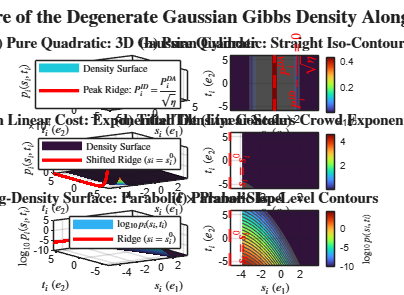

% =========================================================================
% Script: plot_degenerate_gaussian_progression.m
% Description: 3x2 grid illustrating the degenerate Gibbs-Boltzmann density:
%   Row 1: Pure Degenerate Gaussian (No Linear Price Cost, c_t = 0, c_s = 0)
%   Row 2: Degenerate Gaussian multiplied by Exponential Tilt (Linear Scale)
%   Row 3: Full Degenerate Gibbs Density (Log10 Scale)
% =========================================================================

clear; clc; close all;

%% 1. Model Parameters (Tuned for Visual Clarity)
dt       = 1.0;            % Time step duration [h]
alpha_ID = 0.6;            % Intraday penalty coefficient
eta      = 0.8;            % Trade-off parameter (0 < eta <= 1)
pi_DA    = 45;             % Day-ahead price [EUR/MWh]
pi_ID    = 40;             % Intraday price [EUR/MWh]

%% 2. Orthonormal Basis Projections & Geometry
norm_v_sq = (1 / eta) + 1;
norm_v    = sqrt(norm_v_sq);

% Projections of linear cost vector onto {e_1, e_2}
c_s = (dt / norm_v) * ((pi_DA / sqrt(eta)) - pi_ID);
c_t = (dt / norm_v) * (pi_DA + (pi_ID / sqrt(eta)));

% Gaussian variance along s_i
sigma_s_sq = 1 / (alpha_ID * dt * norm_v_sq);
sigma_s    = sqrt(sigma_s_sq);

% Unconstrained optimizers along s_i:
s_0_pure = 0;                                 % For pure quadratic (Row 1)
s_0_tilt = - c_s / (alpha_ID * dt * norm_v_sq); % Shifted by c_i^s (Rows 2 & 3)

% Scaling parameter for the exponential tilt to ensure clear 3D visibility
beta_tilt = 0.035;

%% 3. Coordinate Grids along Orthonormal Axes {e_1, e_2}
s_range = linspace(-4.5 * sigma_s, 4.5 * sigma_s, 220);
t_range = linspace(-6, 6, 220);
[S, T]  = meshgrid(s_range, t_range);

%% 4. Density Computations

% --- Row 1: Pure Degenerate Gaussian (Quadratic Only, No Tilt) ---
% Peak occurs along: s_i = 0  <=>  v^T x_i = 0  <=>  P_i^ID = P_i^DA / sqrt(eta)
P1 = (1 / (sqrt(2 * pi * sigma_s_sq))) .* exp(- S.^2 / (2 * sigma_s_sq));

% --- Row 2: Gaussian with Exponential Tilt (Linear Scale) ---
P2_s = (1 / (sqrt(2 * pi * sigma_s_sq))) .* exp(- (S - s_0_tilt).^2 / (2 * sigma_s_sq));
P2_t = exp(- beta_tilt * c_t .* T);
P2   = P2_s .* P2_t;

% --- Row 3: Gaussian with Exponential Tilt (Log10 Scale) ---
logP3 = log10(max(P2, 1e-10));

%% 5. Plotting (3 x 2 Grid)
figure('Color', 'w', 'Position', [50, 40, 1300, 950]);
cmap = turbo(256);

% Vector along t for drawing the ridge peaks
t_line = linspace(min(t_range), max(t_range), 250);

% =========================================================================
% ROW 1: Pure Degenerate Gaussian
% =========================================================================
% Subplot (1,1): 3D Surface
subplot(3, 2, 1);
surf(S, T, P1, 'EdgeColor', 'none', 'FaceAlpha', 0.95);
hold on; colormap(gca, cmap); shading interp; lighting gouraud; camlight headlight;
P1_ridge = (1 / (sqrt(2 * pi * sigma_s_sq))) * ones(size(t_line));
plot3(zeros(size(t_line)), t_line, P1_ridge, 'r-', 'LineWidth', 2.5);
view(-35, 32); grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
zlabel('$p_i(s_i, t_i)$', 'Interpreter', 'latex');
title('\textbf{(a) Pure Quadratic: 3D Gaussian Cylinder}', 'Interpreter', 'latex', 'FontSize', 11);
legend({'Density Surface', 'Peak Ridge: $P_i^{ID} = \frac{P_i^{DA}}{\sqrt{\eta}}$'}, ...
    'Interpreter', 'latex', 'Location', 'northeast');

% Subplot (1,2): 2D Contour Map
subplot(3, 2, 2);
contourf(S, T, P1, 20, 'LineColor', [0.3 0.3 0.3], 'LineWidth', 0.4);
hold on; colormap(gca, cmap);
xline(0, '--r', 'LineWidth', 2.2, 'Label', '$P_i^{ID} - \frac{P_i^{DA}}{\sqrt{\eta}} = 0$', ...
      'Interpreter', 'latex', 'FontSize', 10, 'LabelVerticalAlignment', 'bottom');
colorbar; grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
title('\textbf{(b) Pure Quadratic: Straight Iso-Contours}', 'Interpreter', 'latex', 'FontSize', 11);

% =========================================================================
% ROW 2: Degenerate Gaussian with Exponential Tilt (Linear Scale)
% =========================================================================
% Subplot (2,1): 3D Surface
subplot(3, 2, 3);
surf(S, T, P2, 'EdgeColor', 'none', 'FaceAlpha', 0.95);
hold on; colormap(gca, cmap); shading interp; lighting gouraud; camlight headlight;
P2_ridge = (1 / (sqrt(2 * pi * sigma_s_sq))) .* exp(- beta_tilt * c_t .* t_line);
plot3(s_0_tilt * ones(size(t_line)), t_line, P2_ridge, 'r-', 'LineWidth', 2.5);
view(-35, 32); grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
zlabel('$p_i(s_i, t_i)$', 'Interpreter', 'latex');
title('\textbf{(c) With Linear Cost: Exponential Tilt (Linear Scale)}', 'Interpreter', 'latex', 'FontSize', 11);
legend({'Density Surface', 'Shifted Ridge ($s_i = s_i^0$)'}, ...
    'Interpreter', 'latex', 'Location', 'northeast');

% Subplot (2,2): 2D Contour Map
subplot(3, 2, 4);
contourf(S, T, P2, 22, 'LineColor', [0.3 0.3 0.3], 'LineWidth', 0.4);
hold on; colormap(gca, cmap);
xline(s_0_tilt, '--r', 'LineWidth', 2.2, 'Label', '$s_i = s_i^0$', ...
      'Interpreter', 'latex', 'FontSize', 10, 'LabelVerticalAlignment', 'bottom');
colorbar; grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
title('\textbf{(d) Tilted Density: Contours Crowd Exponentially}', 'Interpreter', 'latex', 'FontSize', 11);

% =========================================================================
% ROW 3: Degenerate Gaussian with Exponential Tilt (Log10 Scale)
% =========================================================================
% Subplot (3,1): 3D Surface
subplot(3, 2, 5);
surf(S, T, logP3, 'EdgeColor', 'none', 'FaceAlpha', 0.95);
hold on; colormap(gca, cmap); shading interp; lighting gouraud; camlight headlight;
logP3_ridge = log10(max(P2_ridge, 1e-10));
plot3(s_0_tilt * ones(size(t_line)), t_line, logP3_ridge, 'r-', 'LineWidth', 2.5);
view(-35, 32); grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
zlabel('$\log_{10} p_i(s_i, t_i)$', 'Interpreter', 'latex');
title('\textbf{(e) Log-Density Surface: Parabolic $\times$ Planar Slope}', 'Interpreter', 'latex', 'FontSize', 11);
legend({'$\log_{10} p_i(s_i, t_i)$', 'Ridge ($s_i = s_i^0$)'}, ...
    'Interpreter', 'latex', 'Location', 'northeast');

% Subplot (3,2): 2D Contour Map
subplot(3, 2, 6);
levels = linspace(min(logP3(:)), max(logP3(:)), 24);
contourf(S, T, logP3, levels, 'LineColor', [0.3 0.3 0.3], 'LineWidth', 0.4);
hold on; colormap(gca, cmap);
xline(s_0_tilt, '--r', 'LineWidth', 2.2, 'Label', '$s_i = s_i^0$', ...
      'Interpreter', 'latex', 'FontSize', 10, 'LabelVerticalAlignment', 'bottom');
cb = colorbar;
cb.Label.Interpreter = 'latex';
cb.Label.String = '$\log_{10} p_i(s_i, t_i)$';
grid on; box on;
xlabel('$s_i \; (e_1)$', 'Interpreter', 'latex');
ylabel('$t_i \; (e_2)$', 'Interpreter', 'latex');
title('\textbf{(f) Parabolic Iso-Level Contours}', 'Interpreter', 'latex', 'FontSize', 11);

sgtitle('\textbf{Structure of the Degenerate Gaussian Gibbs Density Along $\{e_1, e_2\}$}', ...
    'Interpreter', 'latex', 'FontSize', 14);

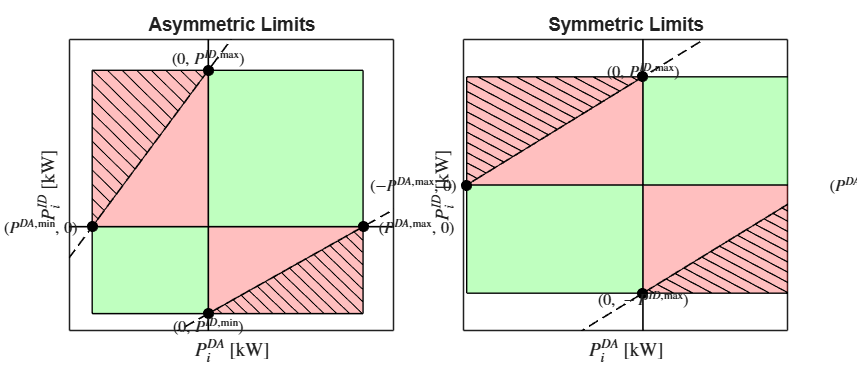

% Clear workspace and figures
clear; clc; close all;

% Global formatting parameters
pointSize = 70;
alphaVal  = 0.25;

% Create a wide figure window
fig = figure('Color','w', 'Position', [100, 100, 1100, 500]); 

% Define explicit, identical sizes for both subplots to force equality
% Format: [left, bottom, width, height] in normalized figures units (0 to 1)
subPlotWidth  = 0.38; 
subPlotHeight = 0.75;
bottomPos     = 0.15;
leftPos1      = 0.08; % Position for the left plot
leftPos2      = 0.54; % Position for the right plot

%% ========================================================================
%  SUBPLOT 1 (LEFT): ASYMMETRIC LIMITS
% ========================================================================
ax1 = axes('Position', [leftPos1, bottomPos, subPlotWidth, subPlotHeight]);
hold(ax1, 'on'); box(ax1, 'on');

% Define asymmetric bounds
P_DA_min = -1.5;
P_DA_max_asym = 2;
P_ID_min = -1.0;
P_ID_max_asym = 1.8;

% Setup padded limits for visualization
xlim_vals1 = [1.2 * P_DA_min, 1.2 * P_DA_max_asym];
ylim_vals1 = [1.2 * P_ID_min, 1.2 * P_ID_max_asym];

% First quadrant rectangle
patch(ax1, [0, 0, P_DA_max_asym, P_DA_max_asym], [0, P_ID_max_asym, P_ID_max_asym, 0], ...
    'g', 'FaceAlpha', alphaVal, 'EdgeColor', 'k');

% Third quadrant rectangle
patch(ax1, [0, 0, P_DA_min, P_DA_min], [0, P_ID_min, P_ID_min, 0], ...
    'g', 'FaceAlpha', alphaVal, 'EdgeColor', 'k');

% 4th quadrant rectangle/triangle area
patch(ax1, [0, 0, P_DA_max_asym, P_DA_max_asym], [0, P_ID_min, P_ID_min, 0], ...
    'r', 'FaceAlpha', alphaVal, 'EdgeColor', 'none');

% 2nd quadrant rectangle/triangle area
patch(ax1, [0, 0, P_DA_min, P_DA_min], [0, P_ID_max_asym, P_ID_max_asym, 0], ...
    'r', 'FaceAlpha', alphaVal, 'EdgeColor', 'none');

% 4th quadrant hatch
h3 = patch(ax1, [P_DA_max_asym, P_DA_max_asym, 0], [0, P_ID_min, P_ID_min], ...
    'w', 'FaceColor','none', 'EdgeColor','k');
hatchfill2(h3, 'HatchStyle','single', 'HatchAngle',-45, 'HatchDensity',30, 'HatchColor','k');

% 2nd quadrant hatch
h4 = patch(ax1, [0, P_DA_min, P_DA_min], [P_ID_max_asym, P_ID_max_asym, 0], ...
    'w', 'FaceColor','none', 'EdgeColor','k');
hatchfill2(h4, 'HatchStyle','single', 'HatchAngle',-45, 'HatchDensity',30, 'HatchColor','k');

% Diagonal boundary lines
xmin1 = xlim_vals1(1); xmax1 = xlim_vals1(2);
x1 = [xmin1 xmax1];

m_up = P_ID_max_asym / (-P_DA_min);
y1_up = m_up * (x1 - P_DA_min);

m_lo = (-P_ID_min) / P_DA_max_asym;
y1_lo = m_lo * (x1 - P_DA_max_asym);

plot(ax1, x1, y1_up, 'k--', 'LineWidth', 1.2);
plot(ax1, x1, y1_lo, 'k--', 'LineWidth', 1.2);

% Axes
plot(ax1, xlim_vals1, [0 0], 'k', 'LineWidth', 1.2);
plot(ax1, [0 0], ylim_vals1, 'k', 'LineWidth', 1.2);

% Mark points
scatter(ax1, [0, 0, P_DA_max_asym, P_DA_min], [P_ID_max_asym, P_ID_min, 0, 0], pointSize, 'k', 'filled');

offset_x1 = 0.05 * (P_DA_max_asym - P_DA_min);
offset_y1 = 0.05 * (P_ID_max_asym - P_ID_min);

text(ax1, 0, P_ID_max_asym + offset_y1, '$(0,\;P^{ID,\max})$', 'Interpreter','latex', 'HorizontalAlignment','center', 'FontSize',12);
text(ax1, 0, P_ID_min - offset_y1, '$(0,\;P^{ID,\min})$', 'Interpreter','latex', 'HorizontalAlignment','center', 'FontSize',12);
text(ax1, P_DA_max_asym + offset_x1, 0, '$(P^{DA,\max},\;0)$', 'Interpreter','latex', 'HorizontalAlignment','left', 'FontSize',12);
text(ax1, P_DA_min - offset_x1, 0, '$(P^{DA,\min},\;0)$', 'Interpreter','latex', 'HorizontalAlignment','right', 'FontSize',12);

xlabel(ax1, '$P^{DA}_i$ [kW]', 'Interpreter','latex', 'FontSize',14);
ylabel(ax1, '$P^{ID}_i$ [kW]', 'Interpreter','latex', 'FontSize',14);
title(ax1, 'Asymmetric Limits', 'FontSize', 14);
xlim(ax1, xlim_vals1); ylim(ax1, ylim_vals1);
set(ax1, 'XTick', [], 'YTick', []);


%% ========================================================================
%  SUBPLOT 2 (RIGHT): SYMMETRIC LIMITS
% ========================================================================
ax2 = axes('Position', [leftPos2, bottomPos, subPlotWidth, subPlotHeight]);
hold(ax2, 'on'); box(ax2, 'on');

P_DA_max = 1.3;
P_ID_max = 1.0;

xlim_vals2 = 1.35 * [-P_DA_max, P_DA_max];
ylim_vals2 = 1.35 * [-P_ID_max, P_ID_max];

% First quadrant rectangle
patch(ax2, [0, 0, P_DA_max, P_DA_max], [0, P_ID_max, P_ID_max, 0], ...
    'g', 'FaceAlpha', alphaVal, 'EdgeColor', 'k');

% Third quadrant rectangle
patch(ax2, [0, 0, -P_DA_max, -P_DA_max], [0, -P_ID_max, -P_ID_max, 0], ...
    'g', 'FaceAlpha', alphaVal, 'EdgeColor', 'k');

% 2nd and 4th quadrant triangles (underlying red fill)
patch(ax2, [0, 0, P_DA_max, P_DA_max], [0, -P_ID_max, -P_ID_max, 0], ...
    'r', 'FaceAlpha', alphaVal, 'EdgeColor', 'none');

patch(ax2, [0, 0, -P_DA_max, -P_DA_max], [0, P_ID_max, P_ID_max, 0], ...
    'r', 'FaceAlpha', alphaVal, 'EdgeColor', 'none');

% 2nd and 4th quadrant not allowed triangle hatches
h1 = patch(ax2, [P_DA_max, P_DA_max, 0], [0, -P_ID_max, -P_ID_max], ...
    'w', 'FaceColor','none', 'EdgeColor','k');
hatchfill2(h1, 'HatchStyle','single', 'HatchAngle',-45, 'HatchDensity',30, 'HatchColor','k');

h2 = patch(ax2, [0, -P_DA_max, -P_DA_max], [P_ID_max, P_ID_max, 0], ...
    'w', 'FaceColor','none', 'EdgeColor','k');
hatchfill2(h2, 'HatchStyle','single', 'HatchAngle',-45, 'HatchDensity',30, 'HatchColor','k');

% Diagonal boundary lines
xmin2 = xlim_vals2(1); xmax2 = xlim_vals2(2);
m2 = P_ID_max / P_DA_max;
x2 = [xmin2 xmax2];
y2_up = m2 * (x2 + P_DA_max);
y2_lo = m2 * (x2 - P_DA_max);

plot(ax2, x2, y2_up, 'k--', 'LineWidth', 1.2);
plot(ax2, x2, y2_lo, 'k--', 'LineWidth', 1.2);

% Axes
plot(ax2, xlim_vals2, [0 0], 'k', 'LineWidth', 1.2);
plot(ax2, [0 0], ylim_vals2, 'k', 'LineWidth', 1.2);

% Mark points
scatter(ax2, [0, 0, P_DA_max, -P_DA_max], [P_ID_max, -P_ID_max, 0, 0], pointSize, 'k', 'filled');

offset_x2 = 0.05 * P_DA_max;
offset_y2 = 0.05 * P_ID_max;

text(ax2, 0, P_ID_max + offset_y2, '$(0,\;P^{ID,\max})$', 'Interpreter','latex', 'HorizontalAlignment','center', 'FontSize',12);
text(ax2, 0, -P_ID_max - offset_y2, '$(0,\;-P^{ID,\max})$', 'Interpreter','latex', 'HorizontalAlignment','center', 'FontSize',12);
text(ax2, P_DA_max + offset_x2, 0, '$(P^{DA,\max},\;0)$', 'Interpreter','latex', 'HorizontalAlignment','left', 'FontSize',12);
text(ax2, -P_DA_max - offset_x2, 0, '$(-P^{DA,\max},\;0)$', 'Interpreter','latex', 'HorizontalAlignment','right', 'FontSize',12);

xlabel(ax2, '$P^{DA}_i$ [kW]', 'Interpreter','latex', 'FontSize',14);
ylabel(ax2, '$P^{ID}_i$ [kW]', 'Interpreter','latex', 'FontSize',14);
title(ax2, 'Symmetric Limits', 'FontSize', 14);
xlim(ax2, xlim_vals2); ylim(ax2, ylim_vals2);
set(ax2, 'XTick', [], 'YTick', []);


% End of replacement block








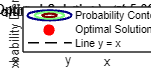


% MATLAB Script to Visualize the PDF of a Quadratic Optimization Problem
clear; clc; close all;

%% 1. Define Cost Function Parameters
% min a*x + b*y + c*x^2 + d*y^2 - 2*e*x*y
%a = DA price
%b = ID price
%c = (gamma + alpha/2)
%d = (gamma + alpha)
%e = gamma

a = 0.07; 
b = 0.06; 
c = 0.01+0.01/2;   % Penalty on x^2
d = 0.01+0.01;   % Penalty on y^2 (Setting c=d forces a 45-degree tilt)
e = 0.01; % Coupling factor (Must satisfy c*d > e^2 for stability)

% Validate positive definiteness
if (c*d <= e^2) || (c <= 0) || (d <= 0)
    error('The cost function is unstable (not strictly convex). Ensure c>0, d>0, and c*d > e^2.');
end

%% 2. Calculate Analytical Mean (\mu) and Covariance (\Sigma)
det_term = 2 * (c*d - e^2);

% Mean vector (\mu) -> The optimal solution coordinates
mu_x = (-b*e - a*d) / det_term;
mu_y = (-a*e - b*c) / det_term;
mu = [mu_x; mu_y];

% Covariance matrix (\Sigma)
Sigma = [d, e; e, c] / det_term;

%% 3. Generate Grid Data for Plotting
% Create a grid centered around the optimal solution (\mu)
grid_span = 3 * max(sqrt(diag(Sigma))); % Look 3 standard deviations out
x_vec = linspace(mu_x - grid_span, mu_x + grid_span, 200);
y_vec = linspace(mu_y - grid_span, mu_y + grid_span, 200);
[X, Y] = meshgrid(x_vec, y_vec);

% Compute Bivariate Gaussian PDF
% Formula: p(x,y) = (1 / (2*pi*sqrt(|Sigma|))) * exp(-0.5 * (z-mu)' * inv(Sigma) * (z-mu))
X_centered = X - mu_x;
Y_centered = Y - mu_y;
invSigma = inv(Sigma);

% Vectorized exponent evaluation
exponent = -0.5 * (invSigma(1,1)*X_centered.^2 + ...
                    2*invSigma(1,2)*X_centered.*Y_centered + ...
                    invSigma(2,2)*Y_centered.^2);
                
norm_factor = 1 / (2 * pi * sqrt(det(Sigma)));
PDF = norm_factor * exp(exponent);

%% 4. Plotting
figure('Position', [100, 100, 1100, 500]);

% --- Left Subplot: 3D Probability Surface ---
subplot(1, 2, 1);
surf(X, Y, PDF, 'EdgeColor', 'none');
colormap(jet);
view(35, 45);
grid on; hold on;

% Mark the MAP / Optimal Solution peak
plot3(mu_x, mu_y, norm_factor, 'r*', 'MarkerSize', 10, 'LineWidth', 2);

title('3D Probability Density Function (PDF)');
xlabel('x'); ylabel('y'); zlabel('Probability Density');
title(sprintf('Probability Peak (Optimal Solution) at (%.2f, %.2f)', mu_x, mu_y));

% --- Right Subplot: 2D Contour Map (Error Ellipses) ---
subplot(1, 2, 2);
[C, h] = contour(X, Y, PDF, 15, 'LineWidth', 1.5);
%clabel(C, h, 'FontSize', 8, 'Color', [0.3 0.3 0.3]);
grid on; hold on;

x_limits = [min(x_vec), max(x_vec)];
y_limits = [min(y_vec), max(y_vec)];

% Plot X-axis (y = 0)
plot(x_limits, [0, 0], 'k-', 'LineWidth', 2, 'Handlevisibility', 'off'); 
% Plot Y-axis (x = 0)
plot([0, 0], y_limits, 'k-', 'LineWidth', 2, 'Handlevisibility', 'off');


% Plot the optimal point
plot(mu_x, mu_y, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);

% Plot the reference line y=x if the tilt is 45 degrees
ref_line_x = linspace(min(x_vec), max(x_vec), 10);
plot(ref_line_x, ref_line_x, 'k--', 'LineWidth', 1);

title('Solution Prediction Cloud in xy-Plane');
xlabel('x'); ylabel('y');
legend('Probability Contours', 'Optimal Solution (MAP)', 'Line y = x', 'Location', 'best');
axis equal; % Ensures geometric angles are accurate

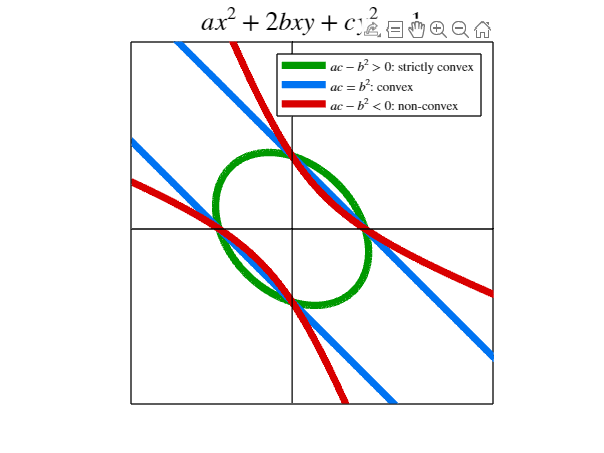

figure('Color','w');
hold on;
axis equal;
box on;

% Grid
[x,y] = meshgrid(linspace(-3,3,800));

%% Strictly convex: ac-b^2 > 0
a = 1;
b = 0.3;
c = 1;
F = a*x.^2 + 2*b*x.*y + c*y.^2;
contour(x,y,F,[1 1], ...
    'LineWidth',5, ...
    'LineColor',[0 0.6 0]);

%% Convex (degenerate): ac-b^2 = 0
a = 1;
b = 1;
c = 1;
F = a*x.^2 + 2*b*x.*y + c*y.^2;
contour(x,y,F,[1 1], ...
    'LineWidth',5, ...
    'LineColor',[0 0.45 0.95]);

%% Non-convex: ac-b^2 < 0
a = 1;
b = 1.5;
c = 1;
F = a*x.^2 + 2*b*x.*y + c*y.^2;
contour(x,y,F,[1 1], ...
    'LineWidth',5, ...
    'LineColor',[0.85 0 0]);

% Axes
plot([-3 3],[0 0],'k','LineWidth',1);
plot([0 0],[-3 3],'k','LineWidth',1);

xlim([-3 3]);
ylim([-3 3]);

set(gca,'XTick',[],'YTick',[]);

legend({ ...
    '$ac-b^2>0$: strictly convex', ...
    '$ac=b^2$: convex', ...
    '$ac-b^2<0$: non-convex'}, ...
    'Interpreter','latex');

title('$ax^2+2bxy+cy^2=1$', ...
    'Interpreter','latex', ...
    'FontSize',18);

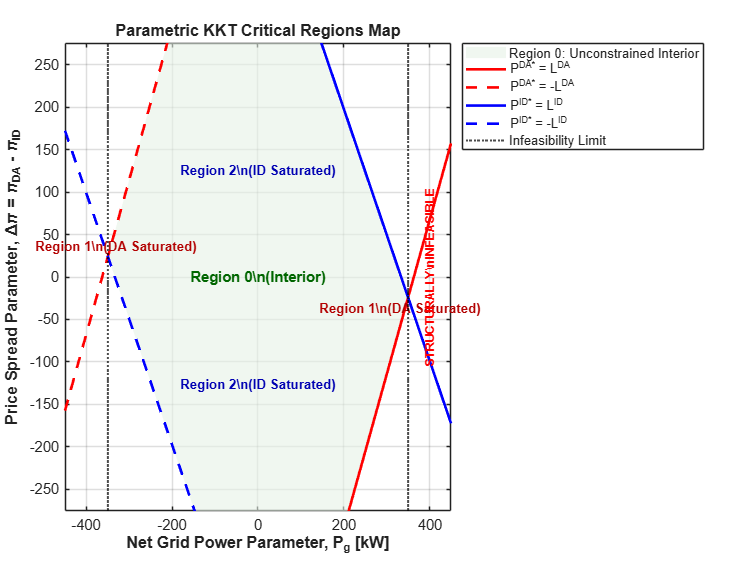

%% Parametric Programming: KKT Critical Regions Visualizer
clear; clc; close all;

% --- 1. Define Optimization Parameters ---
a = 0.5;          % Quadratic cost penalty coefficient
eta = 1.5;        % Market trade-off parameter (\eta > 1 prefers DA)
L_DA = 200;       % Capacity limit for Day-Ahead market [kW]
L_ID = 150;       % Capacity limit for Intraday market [kW]

% Derived structural parameter beta
beta = 1 + 1/sqrt(eta);

% --- 2. Parameter Grid Setup (Axes) ---
% x-axis: Net grid power Pg
% y-axis: Price spread \Delta\pi
Pg_max = L_DA + L_ID + 100; 
Pg = linspace(-Pg_max, Pg_max, 1000);

% --- 3. Compute Analytical KKT Boundary Lines ---
% DA Bounds Active
delta_pi_DA_max = 2*a*beta.*Pg - 2*a*(beta^2)*L_DA;
delta_pi_DA_min = 2*a*beta.*Pg + 2*a*(beta^2)*L_DA;

% ID Bounds Active
delta_pi_ID_max = -2*a*beta*(beta - 1).*Pg + 2*a*(beta^2)*L_ID;
delta_pi_ID_min = -2*a*beta*(beta - 1).*Pg - 2*a*(beta^2)*L_ID;

% --- 4. Identify Intersection Vertices for Polygon Patching ---
% Region 0 is bound by the intersections of these 4 lines
% Int 1: DA_max and ID_max
x1 = (2*a*(beta^2)*L_DA + 2*a*(beta^2)*L_ID) / (2*a*beta + 2*a*beta*(beta-1));
y1 = 2*a*beta*x1 - 2*a*(beta^2)*L_DA;

% Int 2: ID_max and DA_min
x2 = (-2*a*(beta^2)*L_DA + 2*a*(beta^2)*L_ID) / (2*a*beta + 2*a*beta*(beta-1));
y2 = 2*a*beta*x2 + 2*a*(beta^2)*L_DA;

% Int 3: DA_min and ID_min
x3 = -x1; y3 = -y1;

% Int 4: ID_min and DA_max
x4 = -x2; y4 = -y2;

% --- 5. Plotting ---
figure('Color', 'w', 'Position', [100, 100, 850, 650]);
hold on; grid on; box on;

% Fill Region 0 (Unconstrained Interior)
patch([x1, x2, x3, x4], [y1, y2, y3, y4], [0.9 0.95 0.9], ...
      'FaceAlpha', 0.6, 'EdgeColor', 'none', 'DisplayName', 'Region 0: Unconstrained Interior');

% Plot the KKT Boundary Lines
plot(Pg, delta_pi_DA_max, 'r-', 'LineWidth', 2, 'DisplayName', 'P^{DA*} = L^{DA}');
plot(Pg, delta_pi_DA_min, 'r--', 'LineWidth', 2, 'DisplayName', 'P^{DA*} = -L^{DA}');
plot(Pg, delta_pi_ID_max, 'b-', 'LineWidth', 2, 'DisplayName', 'P^{ID*} = L^{ID}');
plot(Pg, delta_pi_ID_min, 'b--', 'LineWidth', 2, 'DisplayName', 'P^{ID*} = -L^{ID}');

% Draw physical grid boundaries (Total structural infeasibility limits)
xline(L_DA + L_ID, 'k:', 'LineWidth', 1.5, 'DisplayName', 'Infeasibility Limit');
xline(-(L_DA + L_ID), 'k:', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% --- 6. Labeling the Critical Regions Text ---
text(0, 0, 'Region 0\n(Interior)', 'HorizontalAlignment', 'center', ...
     'FontSize', 11, 'FontWeight', 'bold', 'Color', [0 0.4 0]);
text(Pg_max-120, 1.5*y1, 'Region 1\n(DA Saturated)', 'HorizontalAlignment', 'center', ...
     'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.7 0 0]);
text(-Pg_max+120, 1.5*y3, 'Region 1\n(DA Saturated)', 'HorizontalAlignment', 'center', ...
     'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.7 0 0]);
text(0, y1+150, 'Region 2\n(ID Saturated)', 'HorizontalAlignment', 'center', ...
     'FontSize', 10, 'FontWeight', 'bold', 'Color', [0 0 0.7]);
text(0, y3-150, 'Region 2\n(ID Saturated)', 'HorizontalAlignment', 'center', ...
     'FontSize', 10, 'FontWeight', 'bold', 'Color', [0 0 0.7]);
text(Pg_max-50, 0, 'STRUCTURALLY\nINFEASIBLE', 'HorizontalAlignment', 'center', ...
     'FontSize', 9, 'FontWeight', 'bold', 'Color', 'r', 'Rotation', 90);

% --- 7. Formatting Graph ---
xlabel('Net Grid Power Parameter, P_g [kW]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Price Spread Parameter, \Delta\pi = \pi_{DA} - \pi_{ID}', 'FontSize', 12, 'FontWeight', 'bold');
title('Parametric KKT Critical Regions Map', 'FontSize', 14, 'FontWeight', 'bold');

xlim([-Pg_max, Pg_max]);
ylim([y3 - 300, y1 + 300]);
legend('Location', 'northeastoutside');
set(gca, 'FontSize', 11);
hold off;

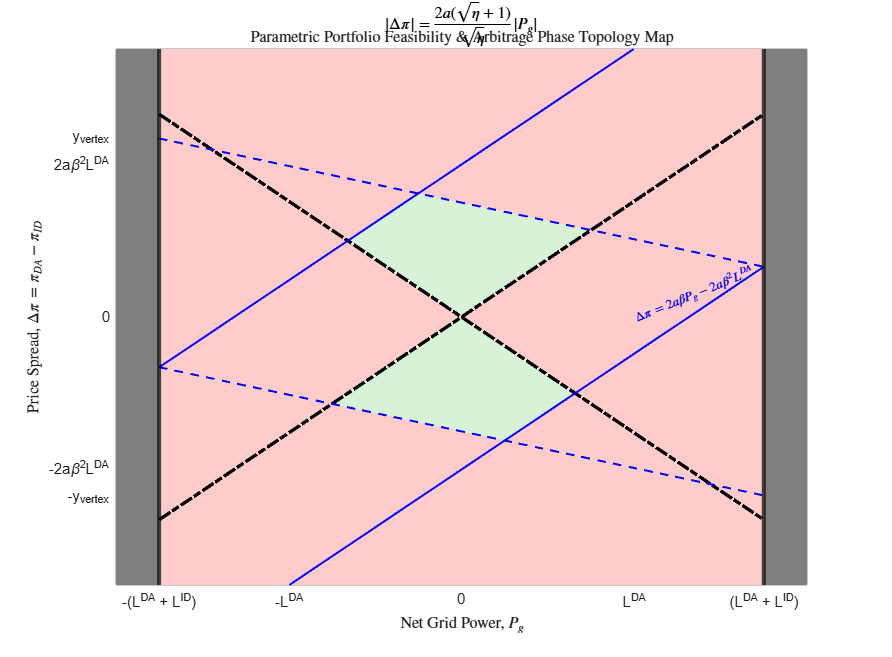

%% Parametric Programming: Portfolio Arbitrage Map
clear; clc; close all;

% --- 1. Define Base Parameters (For structural calculation) ---
a = 0.5;          
eta = 10;        
L_DA = 200;       
L_ID = 150;       

% Derived parameter beta
beta = 1 + 1/sqrt(eta);

% Coordinate Limits based on analytical geometry points
Pg_max = L_DA + L_ID; 
y_vertex = 2*a*beta*L_DA + 2*a*beta*(beta-1)*(L_DA + L_ID); % Boundary height?????????????????
ylim_max = y_vertex + 200;

% Setup dense grid for regional classification matrix
[Pg_grid, dpi_grid] = meshgrid(linspace(-Pg_max-50, Pg_max+50, 2000), linspace(-ylim_max, ylim_max, 2000));

% --- 2. Evaluate Analytical Conditions for Global Segmentation ---
% Condition A: Absolute Physical Infeasibility
Is_Infeasible = abs(Pg_grid) > (L_DA + L_ID);

% Condition B: Active Saturation Bounds (KKT Clipped Paths)
% Unconstrained optimal trajectory equations evaluated at grid pairs
P_DA_opt = Pg_grid./beta - dpi_grid./(2*a*beta^2);
P_ID_opt = Pg_grid.*(1 - 1/beta) + dpi_grid./(2*a*beta^2);

Is_Clipped = (P_DA_opt > L_DA) | (P_DA_opt < -L_DA) | ...
             (P_ID_opt > L_ID) | (P_ID_opt < -L_ID);

% Condition C: Market Arbitrage Threshold (Opposite Signs Trigger Line)
Arbitrage_Threshold = (2 * a * (sqrt(eta) + 1) .* abs(Pg_grid)) ./ sqrt(eta);
Is_Arbitrage = abs(dpi_grid) < Arbitrage_Threshold;

% --- 3. Construct Custom 3-Color Categorical Map ---
% Layer classifications deterministically
Color_Matrix = zeros(size(Pg_grid)); 

% 1 = Light Green (Region 0: Safe/Coordinated Interior)
Color_Matrix(~Is_Infeasible & ~Is_Clipped & ~Is_Arbitrage) = 1; 

% 2 = Light Red (Cross-Market Self-Arbitrage Loops Area)
Color_Matrix(~Is_Infeasible & (Is_Clipped | Is_Arbitrage)) = 2; 

% 3 = Dark Red (Total Structural Infeasibility Zone)
Color_Matrix(Is_Infeasible) = 3;

% --- 4. Plot Graphics Engine ---
figure('Color', 'w', 'Position', [100, 100, 950, 700]);
hold on; axis on; box on;

% Define explicit thematic RGB matrix
Custom_Map = [
    0.85, 0.95, 0.85;   % 1: Soft Pastel Green
    1.00, 0.80, 0.80;   % 2: Soft Pastel Red
    0.5, 0.5, 0.5    % 3: gray
];
colormap(Custom_Map);

% Render continuous spatial background blocks
imagesc(Pg_grid(1,:), dpi_grid(:,1), Color_Matrix);
set(gca, 'YDir', 'normal'); % Prevent graphics engine coordinate inversion

% --- 5. Trace Parametric Bound Overlays ---
Pg_plot = linspace(-Pg_max, Pg_max, 1000);

% Core Threshold Lines: Arbitrage Boundary Condition
plot(Pg_plot, (2*a*(sqrt(eta)+1).*abs(Pg_plot))./sqrt(eta), 'k-.', 'LineWidth', 2.5);
plot(Pg_plot, -(2*a*(sqrt(eta)+1).*abs(Pg_plot))./sqrt(eta), 'k-.', 'LineWidth', 2.5);

% KKT Boundary Lines
plot(Pg_plot, 2*a*beta.*Pg_plot - 2*a*(beta^2)*L_DA, 'b-', 'LineWidth', 1.5);
plot(Pg_plot, 2*a*beta.*Pg_plot + 2*a*(beta^2)*L_DA, 'b-', 'LineWidth', 1.5);
plot(Pg_plot, -2*a*beta*(beta-1).*Pg_plot + 2*a*(beta^2)*L_ID, 'b--', 'LineWidth', 1.5);
plot(Pg_plot, -2*a*beta*(beta-1).*Pg_plot - 2*a*(beta^2)*L_ID, 'b--', 'LineWidth', 1.5);

% Physical Infeasibility Dividers
xline(L_DA + L_ID, 'k-', 'LineWidth', 3);
xline(-(L_DA + L_ID), 'k-', 'LineWidth', 3);

% --- 6. Explicit Parameter-Based Labeling ---
% Parametric line tracking strings using LaTeX interpreter
text(L_DA, 2*a*beta*L_DA - 2*a*(beta^2)*L_DA + 80, '$\Delta\pi = 2a\beta P_g - 2a\beta^2 L^{DA}$', ...
     'Interpreter', 'latex', 'FontSize', 10, 'Rotation', 22, 'Color', 'b', 'FontWeight', 'bold');
text(0, Arbitrage_Threshold(1)+140, '$|\Delta\pi| = \frac{2a(\sqrt{\eta}+1)}{\sqrt{\eta}}|P_g|$', ...
     'Interpreter', 'latex', 'FontSize', 12, 'Color', 'k', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% --- 7. Pure Parametric Axis and Tick Formatter ---
xlabel('Net Grid Power, $P_g$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Price Spread, $\Delta\pi = \pi_{DA} - \pi_{ID}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Parametric Portfolio Feasibility \& Arbitrage Phase Topology Map', 'Interpreter', 'latex', 'FontSize', 14);

% Construct structural parametric coordinate arrays for ticks
XTick_Values = [-(L_DA + L_ID), -L_DA, 0, L_DA, (L_DA + L_ID)];
XTick_Labels = {'-(L^{DA} + L^{ID})', '-L^{DA}', '0', 'L^{DA}', '(L^{DA} + L^{ID})'};

YTick_Values = [-y_vertex, -2*a*(beta^2)*L_DA, 0, 2*a*(beta^2)*L_DA, y_vertex];
YTick_Labels = {'-y_{vertex}', '-2a\beta^2L^{DA}', '0', '2a\beta^2L^{DA}', 'y_{vertex}'};

set(gca, 'XTick', XTick_Values, 'XTickLabel', XTick_Labels, ...
         'YTick', YTick_Values, 'YTickLabel', YTick_Labels, ...
         'FontSize', 11, 'TickLabelInterpreter', 'tex');

% Re-adjust bounds smoothly to fit margins cleanly
xlim([-Pg_max - 50, Pg_max + 50]);
ylim([-ylim_max, ylim_max]);
grid on; hold off;

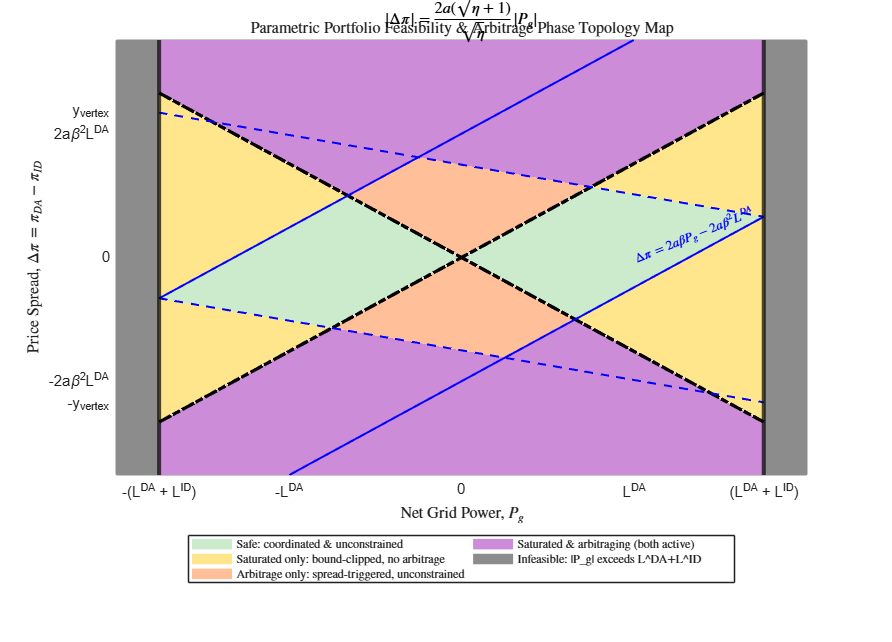

%% Parametric Programming: Portfolio Arbitrage Map
clear; clc; close all;

% --- 1. Define Base Parameters (For structural calculation) ---
a = 0.5;          
eta = 10;        
L_DA = 200;       
L_ID = 150;       

% Derived parameter beta
beta = 1 + 1/sqrt(eta);

% Coordinate Limits based on analytical geometry points
Pg_max = L_DA + L_ID; 
y_vertex = 2*a*beta*L_DA + 2*a*beta*(beta-1)*(L_DA + L_ID); % Boundary height?????????????????
ylim_max = y_vertex + 200;

% Setup dense grid for regional classification matrix
[Pg_grid, dpi_grid] = meshgrid(linspace(-Pg_max-50, Pg_max+50, 2000), linspace(-ylim_max, ylim_max, 2000));

% --- 2. Evaluate Analytical Conditions for Global Segmentation ---
% Condition A: Absolute Physical Infeasibility
Is_Infeasible = abs(Pg_grid) > (L_DA + L_ID);

% Condition B: Active Saturation Bounds (KKT Clipped Paths)
% Unconstrained optimal trajectory equations evaluated at grid pairs
P_DA_opt = Pg_grid./beta - dpi_grid./(2*a*beta^2);
P_ID_opt = Pg_grid.*(1 - 1/beta) + dpi_grid./(2*a*beta^2);

Is_Clipped = (P_DA_opt > L_DA) | (P_DA_opt < -L_DA) | ...
             (P_ID_opt > L_ID) | (P_ID_opt < -L_ID);

% Condition C: Market Arbitrage Threshold (Opposite Signs Trigger Line)
% NOTE: fixed sign -- self-arbitrage is triggered when the price spread
% EXCEEDS the threshold (large |Δπ| makes artificial opposite-sign trading
% profitable), not when it's below it. The original "<" classified the
% safe zone as "arbitrage" and vice versa.
Arbitrage_Threshold = (2 * a * (sqrt(eta) + 1) .* abs(Pg_grid)) ./ sqrt(eta);
Is_Arbitrage = abs(dpi_grid) > Arbitrage_Threshold;

% --- 3. Construct Full Categorical Map (every combination gets its own color) ---
% Layer classifications deterministically. Infeasibility takes precedence
% (a point can't be "clipped" or "arbitraging" if it isn't achievable at
% all), so within the feasible region we separately distinguish all 4
% combinations of {clipped, not-clipped} x {arbitrage, not-arbitrage}.
Color_Matrix = zeros(size(Pg_grid));

feasible = ~Is_Infeasible;

% 1 = Safe interior: feasible, unconstrained, no arbitrage incentive
Color_Matrix(feasible & ~Is_Clipped & ~Is_Arbitrage) = 1;

% 2 = Saturated only: feasible, hits a power bound, but spread is still
%     below the arbitrage trigger (constrained, not self-arbitraging)
Color_Matrix(feasible &  Is_Clipped & ~Is_Arbitrage) = 2;

% 3 = Arbitrage only: feasible, unconstrained optimum sits within bounds,
%     but the price spread alone is enough to trigger opposite-sign trading
Color_Matrix(feasible & ~Is_Clipped &  Is_Arbitrage) = 3;

% 4 = Saturated AND arbitrage: both effects active simultaneously
Color_Matrix(feasible &  Is_Clipped &  Is_Arbitrage) = 4;

% 5 = Structurally infeasible: |Pg| exceeds combined market capacity
Color_Matrix(Is_Infeasible) = 5;

% --- 4. Plot Graphics Engine ---
figure('Color', 'w', 'Position', [100, 100, 1000, 720]);
hold on; axis on; box on;

% Explicit thematic RGB matrix -- one distinct color per category, in the
% same 1..5 order as the codes assigned above
Custom_Map = [
    0.80, 0.92, 0.80;   % 1: Soft green   -- Safe / coordinated interior
    1.00, 0.90, 0.55;   % 2: Soft amber   -- Saturated only (bound-clipped, no arbitrage)
    1.00, 0.75, 0.60;   % 3: Soft orange  -- Arbitrage only (interior, spread-triggered)
    0.80, 0.55, 0.85;   % 4: Soft purple  -- Both saturated and arbitraging
    0.55, 0.55, 0.55;   % 5: Gray         -- Structurally infeasible
];
colormap(Custom_Map);

% Render continuous spatial background blocks; force the color axis to
% span exactly [1,5] so each integer code maps to its intended row
% regardless of whether every category happens to appear in this grid.
imagesc(Pg_grid(1,:), dpi_grid(:,1), Color_Matrix, [1, 5]);
set(gca, 'YDir', 'normal'); % Prevent graphics engine coordinate inversion

% --- 5. Trace Parametric Bound Overlays ---
Pg_plot = linspace(-Pg_max, Pg_max, 1000);

% Core Threshold Lines: Arbitrage Boundary Condition
plot(Pg_plot, (2*a*(sqrt(eta)+1).*abs(Pg_plot))./sqrt(eta), 'k-.', 'LineWidth', 2.5);
plot(Pg_plot, -(2*a*(sqrt(eta)+1).*abs(Pg_plot))./sqrt(eta), 'k-.', 'LineWidth', 2.5);

% KKT Boundary Lines
plot(Pg_plot, 2*a*beta.*Pg_plot - 2*a*(beta^2)*L_DA, 'b-', 'LineWidth', 1.5);
plot(Pg_plot, 2*a*beta.*Pg_plot + 2*a*(beta^2)*L_DA, 'b-', 'LineWidth', 1.5);
plot(Pg_plot, -2*a*beta*(beta-1).*Pg_plot + 2*a*(beta^2)*L_ID, 'b--', 'LineWidth', 1.5);
plot(Pg_plot, -2*a*beta*(beta-1).*Pg_plot - 2*a*(beta^2)*L_ID, 'b--', 'LineWidth', 1.5);

% Physical Infeasibility Dividers
xline(L_DA + L_ID, 'k-', 'LineWidth', 3);
xline(-(L_DA + L_ID), 'k-', 'LineWidth', 3);

% --- 6. Explicit Parameter-Based Labeling ---
text(L_DA, 2*a*beta*L_DA - 2*a*(beta^2)*L_DA + 80, '$\Delta\pi = 2a\beta P_g - 2a\beta^2 L^{DA}$', ...
     'Interpreter', 'latex', 'FontSize', 10, 'Rotation', 22, 'Color', 'b', 'FontWeight', 'bold');
text(0, Arbitrage_Threshold(1,1)+140, '$|\Delta\pi| = \frac{2a(\sqrt{\eta}+1)}{\sqrt{\eta}}|P_g|$', ...
     'Interpreter', 'latex', 'FontSize', 12, 'Color', 'k', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% --- 7. Pure Parametric Axis and Tick Formatter ---
xlabel('Net Grid Power, $P_g$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Price Spread, $\Delta\pi = \pi_{DA} - \pi_{ID}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Parametric Portfolio Feasibility \& Arbitrage Phase Topology Map', 'Interpreter', 'latex', 'FontSize', 14);

XTick_Values = [-(L_DA + L_ID), -L_DA, 0, L_DA, (L_DA + L_ID)];
XTick_Labels = {'-(L^{DA} + L^{ID})', '-L^{DA}', '0', 'L^{DA}', '(L^{DA} + L^{ID})'};

YTick_Values = [-y_vertex, -2*a*(beta^2)*L_DA, 0, 2*a*(beta^2)*L_DA, y_vertex];
YTick_Labels = {'-y_{vertex}', '-2a\beta^2L^{DA}', '0', '2a\beta^2L^{DA}', 'y_{vertex}'};

set(gca, 'XTick', XTick_Values, 'XTickLabel', XTick_Labels, ...
         'YTick', YTick_Values, 'YTickLabel', YTick_Labels, ...
         'FontSize', 11, 'TickLabelInterpreter', 'tex');

xlim([-Pg_max - 50, Pg_max + 50]);
ylim([-ylim_max, ylim_max]);
grid on;

% --- 8. Categorical Legend ---
% imagesc/colorbar don't produce a discrete legend on their own, so add
% invisible proxy patches, one per category, purely to drive the legend.
legend_labels = { ...
    'Safe: coordinated \& unconstrained', ...
    'Saturated only: bound-clipped, no arbitrage', ...
    'Arbitrage only: spread-triggered, unconstrained', ...
    'Saturated \& arbitraging (both active)', ...
    'Infeasible: |P_g| exceeds L^{DA}+L^{ID}'};
h_proxy = gobjects(5,1);
for k = 1:5
    h_proxy(k) = patch(NaN, NaN, Custom_Map(k,:), 'EdgeColor', 'none');
end
legend(h_proxy, legend_labels, 'Interpreter', 'latex', 'Location', 'southoutside', ...
       'FontSize', 9, 'NumColumns', 2);

hold off;


%%
%% Pareto Front Analysis for Battery Cost Function
%
%   J(x,y) = 5x + 6y + a*(x - y/sqrt(n))^2
%
%   J1(x,y) = 5x + 6y          (linear market cost)
%   J2(x,y) = (x - y/sqrt(n))^2  (quadratic structural deviation)
%
%   The combined cost is J = J1 + a*J2, so 'a' is the Pareto weight.
%   'n' reshapes the penalty geometry (target ratio: x = y/sqrt(n)).
%
%   CASE 1: Both a and n vary  -> Pareto surface / family of frontiers
%   CASE 2: a fixed, n varies  -> Single Pareto curve

clear; clc; close all;

%% ── Solver: analytical optimal (x*,y*) for given a and n ────────────────
%
%  Unconstrained minimum of J(x,y):
%    dJ/dx = 5 + 2a(x - y/sqrt(n))       = 0
%    dJ/dy = 6 - 2a(x - y/sqrt(n))/sqrt(n) + 2a*y/n  ... wait
%
%  Expanding the quadratic:  a*(x^2 + y^2/n - 2xy/sqrt(n))
%    dJ/dx = 5 + 2a*x - 2a*y/sqrt(n) = 0   ...(1)
%    dJ/dy = 6 - 2a*x/sqrt(n) + 2a*y/n = 0 ...(2)
%
%  Linear system:  A*[x;y] = b
%    A = [2a,          -2a/sqrt(n);
%        -2a/sqrt(n),   2a/n      ]
%    b = [-5; -6]



%% ── Objective evaluators ────────────────────────────────────────────────

J1 = @(x,y)       5*x + 6*y;
J2 = @(x,y,n)     (x - y./sqrt(n)).^2;

%% ── Pareto filter: keep non-dominated points ────────────────────────────
%  A point p dominates q iff p.J1 <= q.J1 AND p.J2 <= q.J2 (strict one).



%% ════════════════════════════════════════════════════════════════════════
%% CASE 1: Both a and n vary
%% ════════════════════════════════════════════════════════════════════════

a_vals = logspace(-2, 2, 30);        % 30 values: 0.01 → 100
n_vals = [1, 2, 5, 10, 20, 50];      % representative n values

% Colour map: one colour per n value
cmap = lines(length(n_vals));

% Storage for all solutions
all_J1 = [];
all_J2 = [];
all_n  = [];
all_a  = [];

figure('Name','Case 1: Both a and n vary','NumberTitle','off', ...
       'Position',[100 100 900 600]);
hold on; grid on; box on;

leg_handles = gobjects(length(n_vals), 1);

for ni = 1:length(n_vals)
    n  = n_vals(ni);
    j1 = zeros(length(a_vals), 1);
    j2 = zeros(length(a_vals), 1);
    valid = true(length(a_vals), 1);

    for ai = 1:length(a_vals)
        a = a_vals(ai);
        [x_opt, y_opt] = solve_xy(a, n);
        if isnan(x_opt)
            valid(ai) = false;
            continue;
        end
        j1(ai) = J1(x_opt, y_opt);
        j2(ai) = J2(x_opt, y_opt, n);
    end

    j1 = j1(valid);
    j2 = j2(valid);
    a_plot = a_vals(valid);

    all_J1 = [all_J1; j1];
    all_J2 = [all_J2; j2];
    all_n  = [all_n;  repmat(n, length(j1), 1)];
    all_a  = [all_a;  a_plot(:)];

    % Scatter: each point is one (a,n) solution
    scatter(j2, j1, 40, cmap(ni,:), 'filled', 'MarkerFaceAlpha', 0.5);

    % Connect points for this n with a thin line (sorted by J2)
    [j2s, idx] = sort(j2);
    leg_handles(ni) = plot(j2s, j1(idx), '-', 'Color', cmap(ni,:), ...
                           'LineWidth', 1.2, ...
                           'DisplayName', sprintf('n = %d', n));
end

% Global Pareto frontier across ALL (a,n) combinations
front1 = pareto_filter(all_J1, all_J2);
plot(front1.J2, front1.J1, 'k--', 'LineWidth', 2.5, ...
     'DisplayName', 'Global Pareto frontier');

% Annotate the frontier with a few (a,n) labels
% find closest solution to each frontier point
for fi = 1:2:length(front1.J1)
    dist = (all_J1 - front1.J1(fi)).^2 + (all_J2 - front1.J2(fi)).^2;
    [~, idx] = min(dist);
    text(front1.J2(fi), front1.J1(fi), ...
         sprintf('  a=%.2g\n  n=%d', all_a(idx), all_n(idx)), ...
         'FontSize', 7, 'Color', [0.3 0.3 0.3]);
end

xlabel('J_2 = (x - y/\surd n)^2   [quadratic deviation]', 'FontSize', 12);
ylabel('J_1 = 5x + 6y   [market cost]',                   'FontSize', 12);
title('Pareto Frontier — Both \ita\rm and \itn\rm vary',   'FontSize', 13);
legend([leg_handles; findobj(gca,'DisplayName','Global Pareto frontier')], ...
       'Location','northeast', 'FontSize', 9);
hold off;

%% ════════════════════════════════════════════════════════════════════════
%% CASE 2: a fixed, n varies
%% ════════════════════════════════════════════════════════════════════════

a_fixed_vals = [0.1, 1.0, 10.0];     % try three representative fixed a values
n_sweep      = linspace(1, 50, 200); % dense sweep of n

cmap2 = [0.10 0.37 0.65;   % blue   (a=0.1)
         0.11 0.62 0.46;   % teal   (a=1.0)
         0.85 0.35 0.19];  % coral  (a=10)

figure('Name','Case 2: a fixed, n varies','NumberTitle','off', ...
       'Position',[200 150 900 600]);
hold on; grid on; box on;

for ai = 1:length(a_fixed_vals)
    a  = a_fixed_vals(ai);
    j1 = zeros(length(n_sweep), 1);
    j2 = zeros(length(n_sweep), 1);
    valid = true(length(n_sweep), 1);

    for ni = 1:length(n_sweep)
        n = n_sweep(ni);
        [x_opt, y_opt] = solve_xy(a, n);
        if isnan(x_opt)
            valid(ni) = false;
            continue;
        end
        j1(ni) = J1(x_opt, y_opt);
        j2(ni) = J2(x_opt, y_opt, n);
    end

    j1 = j1(valid);
    j2 = j2(valid);
    n_valid = n_sweep(valid);

    % Plot curve
    plot(j2, j1, '-', 'Color', cmap2(ai,:), 'LineWidth', 2.0, ...
         'DisplayName', sprintf('a = %.1f', a));

    % Mark minimum J1 (best market cost)
    [~, imin_j1] = min(j1);
    scatter(j2(imin_j1), j1(imin_j1), 100, cmap2(ai,:), ...
            'o', 'filled', 'HandleVisibility','off');
    text(j2(imin_j1), j1(imin_j1), ...
         sprintf('  n=%.0f\n  (min J_1)', n_valid(imin_j1)), ...
         'FontSize', 8, 'Color', cmap2(ai,:));

    % Mark minimum J2 (least deviation)
    [~, imin_j2] = min(j2);
    scatter(j2(imin_j2), j1(imin_j2), 100, cmap2(ai,:), ...
            's', 'filled', 'HandleVisibility','off');
    text(j2(imin_j2), j1(imin_j2), ...
         sprintf('  n=%.0f\n  (min J_2)', n_valid(imin_j2)), ...
         'FontSize', 8, 'Color', cmap2(ai,:));

    % Arrows along the curve showing direction of increasing n
    arrow_idxs = round(linspace(10, length(j1)-10, 4));
    for k = arrow_idxs
        if k+1 > length(j1); continue; end
        dx = j2(k+1) - j2(k);
        dy = j1(k+1) - j1(k);
        quiver(j2(k), j1(k), dx*0.001, dy*0.001, 0, ...
               'Color', cmap2(ai,:), 'MaxHeadSize', 60, ...
               'LineWidth', 0.8, 'HandleVisibility','off');
    end
end

xlabel('J_2 = (x - y/\surd n)^2   [quadratic deviation]', 'FontSize', 12);
ylabel('J_1 = 5x + 6y   [market cost]',                   'FontSize', 12);
title('Pareto Curve — \ita\rm fixed, \itn\rm varies',      'FontSize', 13);
legend('Location','northeast', 'FontSize', 10);

% Annotation explaining markers
annotation('textbox', [0.13 0.15 0.28 0.10], ...
    'String', {'\circ  minimum J_1 (best market cost)', ...
               '\square  minimum J_2 (least deviation)', ...
               '\rightarrow  direction of increasing n'}, ...
    'FontSize', 8, 'EdgeColor', [0.8 0.8 0.8], ...
    'BackgroundColor', [0.97 0.97 0.97]);
hold off;

%% ════════════════════════════════════════════════════════════════════════
%% CASE 2b: Single a — n-labelled curve with colorbar
%% ════════════════════════════════════════════════════════════════════════

a  = 1.0;    % fix a here — change to your calibrated value
n_sweep = linspace(1, 50, 300);

j1 = zeros(length(n_sweep), 1);
j2 = zeros(length(n_sweep), 1);
valid = true(length(n_sweep), 1);

for ni = 1:length(n_sweep)
    n = n_sweep(ni);
    [x_opt, y_opt] = solve_xy(a, n);
    if isnan(x_opt); valid(ni) = false; continue; end
    j1(ni) = J1(x_opt, y_opt);
    j2(ni) = J2(x_opt, y_opt, n);
end
j1 = j1(valid);
j2 = j2(valid);
n_valid = n_sweep(valid);

figure('Name','Case 2b: a=1 fixed, n coloured','NumberTitle','off', ...
       'Position',[300 200 800 550]);

% Use scatter with colour = n value
scatter(j2, j1, 30, n_valid, 'filled');
cb = colorbar;
cb.Label.String = 'n value';
cb.Label.FontSize = 11;
colormap(gca, parula);

hold on; grid on; box on;

% Overlay the Pareto-efficient subset
front2 = pareto_filter(j1, j2);
plot(front2.J2, front2.J1, 'k--', 'LineWidth', 2, ...
     'DisplayName', 'Pareto frontier');

% Mark elbow: point of maximum curvature (approx)
% Use the point maximising distance from the straight line connecting
% the two extreme frontier points.
p1 = [front2.J2(1),   front2.J1(1)];
p2 = [front2.J2(end), front2.J1(end)];
nf = length(front2.J1);
if nf > 2
    d  = abs((p2(2)-p1(2))*front2.J2 - (p2(1)-p1(1))*front2.J1 + ...
              p2(1)*p1(2) - p2(2)*p1(1)) / norm(p2-p1);
    [~, elbow_idx] = max(d);
    scatter(front2.J2(elbow_idx), front2.J1(elbow_idx), 150, 'r', ...
            'p', 'filled', 'DisplayName', 'Elbow (suggested \lambda)');
    text(front2.J2(elbow_idx), front2.J1(elbow_idx), ...
         sprintf('  Elbow\n  n \\approx %.0f', ...
         interp1(j2, n_valid, front2.J2(elbow_idx), 'nearest')), ...
         'FontSize', 9, 'Color', 'r');
end

xlabel('J_2 = (x - y/\surd n)^2   [quadratic deviation]', 'FontSize', 12);
ylabel('J_1 = 5x + 6y   [market cost]',                   'FontSize', 12);
title(sprintf('Pareto Curve — a = %.1f fixed, n coloured', a), 'FontSize', 13);
legend('Location','northeast', 'FontSize', 10);
hold off;

fprintf('\n── Done. Three figures generated. ──\n');
fprintf('Figure 1: Both a and n vary  (global Pareto frontier)\n');
fprintf('Figure 2: a fixed at 3 values, n sweeps  (curves with markers)\n');
fprintf('Figure 3: a=%.1f fixed, n coloured  (elbow detection)\n', a);


fileName = 'energy_market_erratic.xlsx';

%% Parameters
PV = load("pv.mat");
PV = PV.PV;
t = linspace(0, 24, 96)

t =          0    0.2526    0.5053    0.7579    1.0105    1.2632    1.5158    1.7684    2.0211    2.2737    2.5263    2.7789    3.0316    3.2842    3.5368    3.7895    4.0421    4.2947    4.5474    4.8000    5.0526    5.3053    5.5579    5.8105    6.0632    6.3158    6.5684    6.8211    7.0737    7.3263    7.5789    7.8316    8.0842    8.3368    8.5895    8.8421    9.0947    9.3474    9.6000    9.8526   10.1053   10.3579   10.6105   10.8632   11.1158   11.3684   11.6211   11.8737   12.1263   12.3789


sheetIdx = 2

sheetIdx = 2

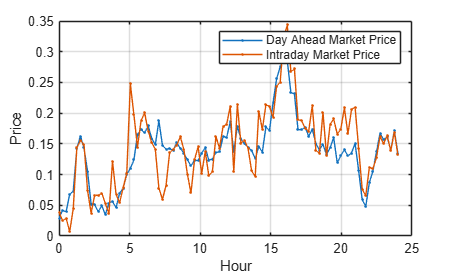


data = readmatrix(fileName, 'Sheet', sheetIdx);
p_DA = data(:, 2)';
p_ID = data(:, 3)';
P_L_eff  = data(:, 4)'-PV;

figure()
plot(t, p_DA, '.', 'LineStyle','-')
hold on
plot(t, p_ID, '.', 'LineStyle','-')
grid on
xlabel('Hour')
ylabel('Price')
legend('Day Ahead Market Price', 'Intraday Market Price')

%plot(P_L_eff)



function front = pareto_filter(J1_vals, J2_vals)
    n_pts = length(J1_vals);
    is_nd = true(n_pts, 1);          % non-dominated flag
    for i = 1:n_pts
        for j = 1:n_pts
            if i == j; continue; end
            if J1_vals(j) <= J1_vals(i) && J2_vals(j) <= J2_vals(i) && ...
               (J1_vals(j) < J1_vals(i) || J2_vals(j) < J2_vals(i))
                is_nd(i) = false;
                break;
            end
        end
    end
    front.J1  = J1_vals(is_nd);
    front.J2  = J2_vals(is_nd);
    % Sort by J2 for clean plotting
    [front.J2, idx] = sort(front.J2);
    front.J1 = front.J1(idx);
end

function [x_opt, y_opt] = solve_xy(a, n)
    A = [2*a,          -2*a/sqrt(n);
        -2*a/sqrt(n),   2*a/n      ];
    b = [-5; -6];
    % Check conditioning; fall back to large positive values if singular
    if abs(det(A)) < 1e-10
        x_opt = NaN;
        y_opt = NaN;
        return;
    end
    sol   = A \ b;
    x_opt = sol(1);
    y_opt = sol(2);
end